## Control PI Por Asignación de Polos (sengundo Orden)

**Por:** Sergio Andres Castaño Giraldo

Universidade Federal de Rio de Janeiro

Rio de Janeiro - 2020

[http://controlautomaticoeducacion.com](http://controlautomaticoeducacion.com)

clc
clear all
close all

### Función de transferencia del proceso

Para este caso se desea controlar el nivel del segundo tanque ($h_2$) en un sistema de dos tanques en cascada.

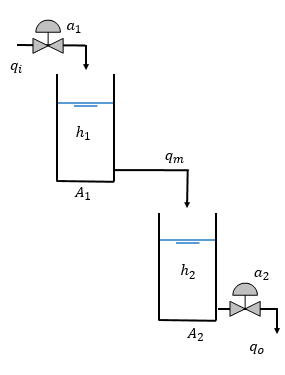

La función de transferencia viene dado por:


$$P = \frac{0.0006}{s^2+0.03271s+0.0002297}$$


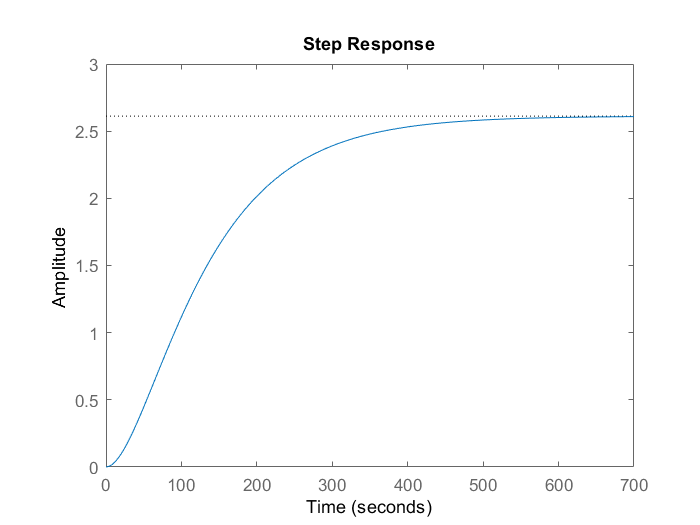

P=tf(0.0006,[1 0.03271 0.0002297]);
step(P)


%Obtiene la Ganancia de la Planta
k=dcgain(P);
%Obtiene el numerador y denominador de la FT
[n,d]=tfdata(P,'v');
L=P.iodelay;
a=d(2);
b=d(3);


### Ecuación característica de Lazo cerrado


$$P=s^3+as^2+(b+kK_p)s+kK_i$$


### PI por Asignación de Polos

Se procede a encontrar el control por asignación de Polos por medio de unas condiciones de diseño. En este caso se establecen dons polos complejos conjugados y un polo real

% Especificaciones de Diseño
Mp=25; %Maximo Pico
ep=sqrt(((log(Mp/100))^2)/(pi^2+((log(Mp/100))^2)));
Tss = 400;
Wn=4/(ep*Tss);

El polo real es el encargado de reducir el máximo sobreimpulso y tambien aumentar o disminuir el tiempo de establecimiento. La proporción del polo real con los polos complejos conjugados es dado por:


$$\beta=\frac{p_1}{\zeta\omega}$$


Si la proporción es 1 no existirá sobreimpulso, a medida que aumenta la respuesta presenta mayor sobreimpulso

% beta = 1.1; %Proporción del polo real
beta = a/(ep*Wn) - 2

beta = 1.2710

Calculo de los polos deseados según la ecuación característica:


$$P_d =s^3 +\left(p_1 +2\zeta \;\omega {\;}_{n\;} \right)s^2 +\left({2p}_1 \zeta \;\omega {\;}_{n\;} +\omega_n^2 \right)s+p_1 \omega_n^{2\;}$$


Sd=[-ep*Wn+1i*Wn*sqrt(1-ep^2), -ep*Wn-1i*Wn*sqrt(1-ep^2)]; %Alocação de Polos
Sd1=[Sd -beta*ep*Wn];
%Ecuación característica deseada
Pds=poly(Sd1);


Calculo de los parámetros del controlador

Kc=((2*beta*ep^2+1)*Wn^2-b)/n(3);        %Calculo de Kc
Ki=(beta*ep*Wn^3)/n(3);     %Calculo de ti
ti=Kc/Ki;
td=0;

%Controlador PI
C=tf(Kc*[ti*td ti 1],[ti 0]);

### Resultados

%Simulación con el Modelo en lazo cerrado
H=minreal((C*P)/(1+C*P));
Hi = stepinfo(H);

[pole(H) Sd1']

ans =   -0.0100 + 0.0227i  -0.0100 - 0.0227i
  -0.0100 - 0.0227i  -0.0100 + 0.0227i
  -0.0127 + 0.0000i  -0.0127 + 0.0000i


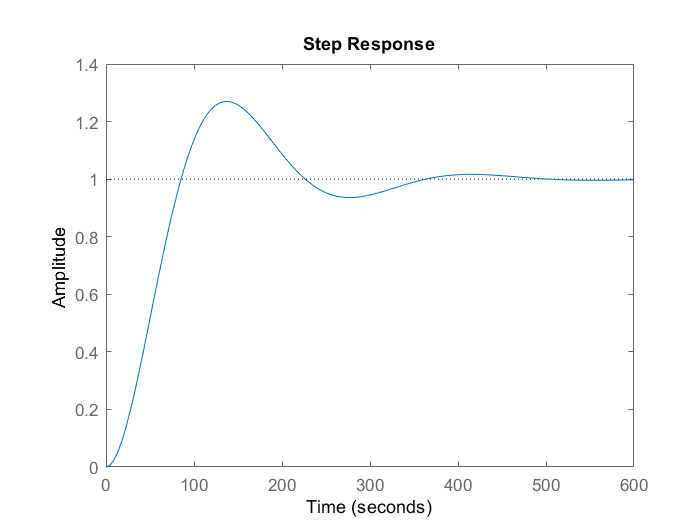

step(H);

Hi

Hi = struct with fields:
        RiseTime: 57.8088
    SettlingTime: 338.8704
     SettlingMin: 0.9190
     SettlingMax: 1.2699
       Overshoot: 26.9936
      Undershoot: 0
            Peak: 1.2699
        PeakTime: 138.1551


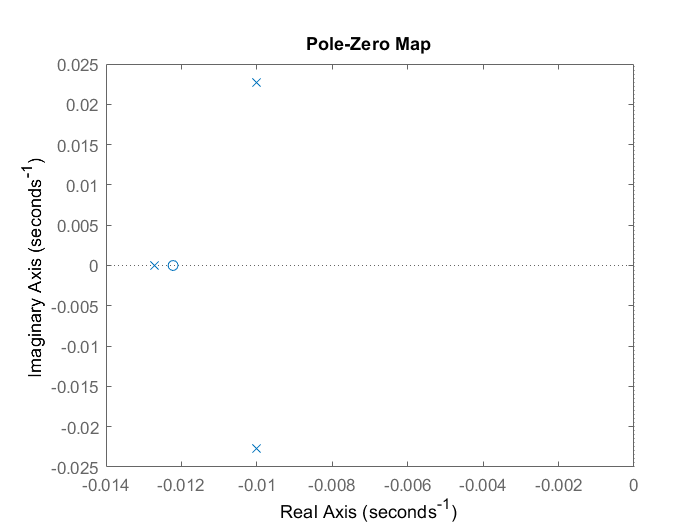

figure
pzmap(H);